clc
clear
close all

epsilon = [0, 0.02, 0.05, 0.1, 0.15, 0.2, 0.25, 0.3]*100;

out_0_per = load("./sims/sim_0_per.mat").out;
out_2_per = load("./sims/sim_2_per.mat").out;
out_5_per = load("./sims/sim_5_per.mat").out;
out_10_per = load("./sims/sim_10_per.mat").out;
out_15_per = load("./sims/sim_15_per.mat").out;
out_20_per = load("./sims/sim_20_per.mat").out;
out_25_per = load("./sims/sim_25_per.mat").out;
out_30_per = load("./sims/sim_30_per.mat").out;

out_0_per_2 = load("./sims2/sim_0_per.mat").out;
out_2_per_2 = load("./sims2/sim_2_per.mat").out;
out_5_per_2 = load("./sims2/sim_5_per.mat").out;
out_10_per_2 = load("./sims2/sim_10_per.mat").out;
out_15_per_2 = load("./sims2/sim_15_per.mat").out;
out_20_per_2 = load("./sims2/sim_20_per.mat").out;
out_25_per_2 = load("./sims2/sim_25_per.mat").out;
out_30_per_2 = load("./sims2/sim_30_per.mat").out;


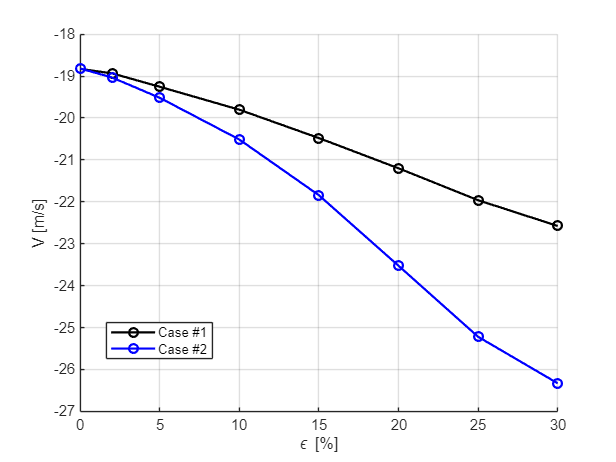

vec_data = [];
vec_data(1, 1) = out_0_per.vehicle_velocity(end,3);
vec_data(1, 2) = out_2_per.vehicle_velocity(end,3);
vec_data(1, 3) = out_5_per.vehicle_velocity(end,3);
vec_data(1, 4) = out_10_per.vehicle_velocity(end,3);
vec_data(1, 5) = out_15_per.vehicle_velocity(end,3);
vec_data(1, 6) = out_20_per.vehicle_velocity(end,3);
vec_data(1, 7) = out_25_per.vehicle_velocity(end,3);
vec_data(1, 8) = out_30_per.vehicle_velocity(end,3);

vec_data(2, 1) = out_0_per_2.vehicle_velocity(end,3);
vec_data(2, 2) = out_2_per_2.vehicle_velocity(end,3);
vec_data(2, 3) = out_5_per_2.vehicle_velocity(end,3);
vec_data(2, 4) = out_10_per_2.vehicle_velocity(end,3);
vec_data(2, 5) = out_15_per_2.vehicle_velocity(end,3);
vec_data(2, 6) = out_20_per_2.vehicle_velocity(end,3);
vec_data(2, 7) = out_25_per_2.vehicle_velocity(end,3);
vec_data(2, 8) = out_30_per_2.vehicle_velocity(end,3);

figure() 
hold on
plot(epsilon, vec_data(1, :), "ko-", 'LineWidth', 1.5, "DisplayName", "Case #1")
plot(epsilon, vec_data(2, :), "bo-", 'LineWidth', 1.5, "DisplayName", "Case #2")
hold off
grid on
legend("Location","best")
xlabel("\epsilon [%]")
ylabel("V [m/s]")
set(gcf, 'PaperPositionMode', 'auto')
print(gcf, 'rootcutout_vehicle_velocity_cases', '-depsc')  % EPS a cores

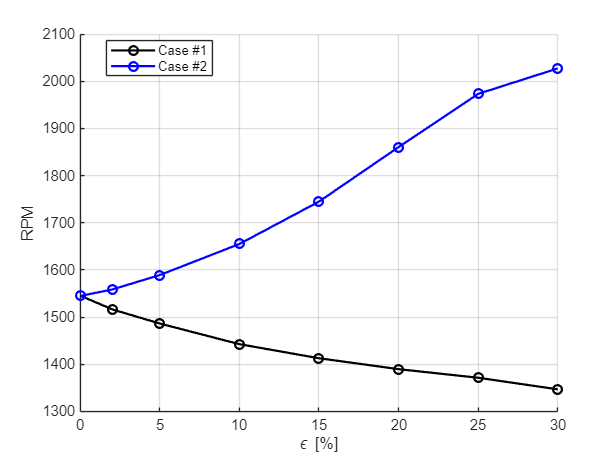


vec_data = [];
vec_data(1, 1) = out_0_per.rotor_rpm(end);
vec_data(1, 2) = out_2_per.rotor_rpm(end);
vec_data(1, 3) = out_5_per.rotor_rpm(end);
vec_data(1, 4) = out_10_per.rotor_rpm(end);
vec_data(1, 5) = out_15_per.rotor_rpm(end);
vec_data(1, 6) = out_20_per.rotor_rpm(end);
vec_data(1, 7) = out_25_per.rotor_rpm(end);
vec_data(1, 8) = out_30_per.rotor_rpm(end);

vec_data(2, 1) = out_0_per_2.rotor_rpm(end);
vec_data(2, 2) = out_2_per_2.rotor_rpm(end);
vec_data(2, 3) = out_5_per_2.rotor_rpm(end);
vec_data(2, 4) = out_10_per_2.rotor_rpm(end);
vec_data(2, 5) = out_15_per_2.rotor_rpm(end);
vec_data(2, 6) = out_20_per_2.rotor_rpm(end);
vec_data(2, 7) = out_25_per_2.rotor_rpm(end);
vec_data(2, 8) = out_30_per_2.rotor_rpm(end);

figure() 
hold on
plot(epsilon, vec_data(1, :), "ko-", 'LineWidth', 1.5, "DisplayName", "Case #1")
plot(epsilon, vec_data(2, :), "bo-", 'LineWidth', 1.5, "DisplayName", "Case #2")
hold off
grid on
legend("Location","best")
xlabel("\epsilon [%]")
ylabel("RPM")
set(gcf, 'PaperPositionMode', 'auto')
print(gcf, 'rootcutout_rotor_velocity_cases', '-depsc')  % EPS a cores

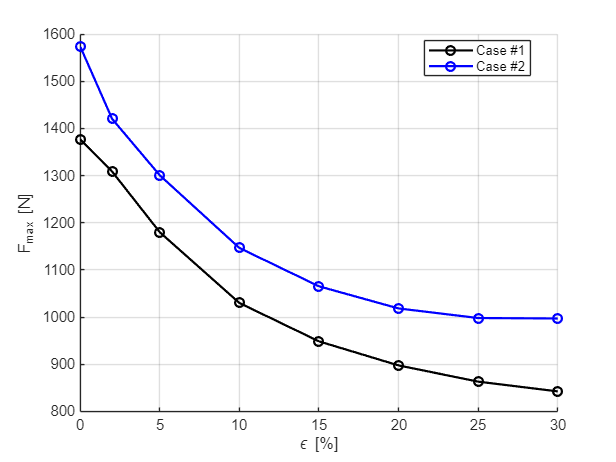


vec_data = [];
vec_data(1, 1) = max(out_0_per.F_rotor(:,3));
vec_data(1, 2) = max(out_2_per.F_rotor(:,3));
vec_data(1, 3) = max(out_5_per.F_rotor(:,3));
vec_data(1, 4) = max(out_10_per.F_rotor(:,3));
vec_data(1, 5) = max(out_15_per.F_rotor(:,3));
vec_data(1, 6) = max(out_20_per.F_rotor(:,3));
vec_data(1, 7) = max(out_25_per.F_rotor(:,3));
vec_data(1, 8) = max(out_30_per.F_rotor(:,3));

vec_data(2, 1) = max(out_0_per_2.F_rotor(:,3));
vec_data(2, 2) = max(out_2_per_2.F_rotor(:,3));
vec_data(2, 3) = max(out_5_per_2.F_rotor(:,3));
vec_data(2, 4) = max(out_10_per_2.F_rotor(:,3));
vec_data(2, 5) = max(out_15_per_2.F_rotor(:,3));
vec_data(2, 6) = max(out_20_per_2.F_rotor(:,3));
vec_data(2, 7) = max(out_25_per_2.F_rotor(:,3));
vec_data(2, 8) = max(out_30_per_2.F_rotor(:,3));

figure() 
hold on
plot(epsilon, vec_data(1, :), "ko-", 'LineWidth', 1.5, "DisplayName", "Case #1")
plot(epsilon, vec_data(2, :), "bo-", 'LineWidth', 1.5, "DisplayName", "Case #2")
hold off
grid on
legend("Location","best")
xlabel("\epsilon [%]")
ylabel("F_{max} [N]")
set(gcf, 'PaperPositionMode', 'auto')
print(gcf, 'rootcutout_rotor_force_cases', '-depsc')  % EPS a cores

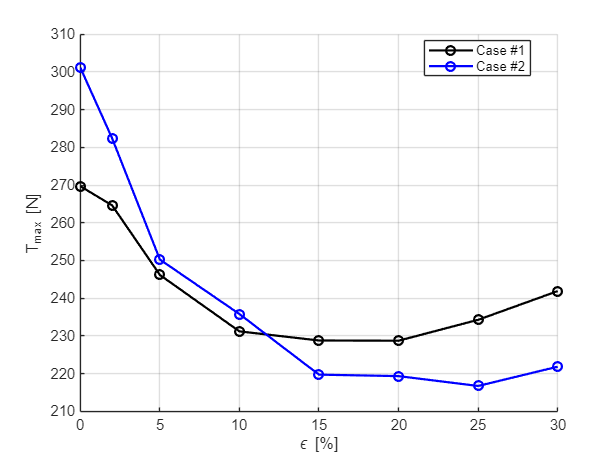


vec_data = [];
vec_data(1, 1) = max(out_0_per.T_rotor);
vec_data(1, 2) = max(out_2_per.T_rotor);
vec_data(1, 3) = max(out_5_per.T_rotor);
vec_data(1, 4) = max(out_10_per.T_rotor);
vec_data(1, 5) = max(out_15_per.T_rotor);
vec_data(1, 6) = max(out_20_per.T_rotor);
vec_data(1, 7) = max(out_25_per.T_rotor);
vec_data(1, 8) = max(out_30_per.T_rotor);

vec_data(2, 1) = max(out_0_per_2.T_rotor);
vec_data(2, 2) = max(out_2_per_2.T_rotor);
vec_data(2, 3) = max(out_5_per_2.T_rotor);
vec_data(2, 4) = max(out_10_per_2.T_rotor);
vec_data(2, 5) = max(out_15_per_2.T_rotor);
vec_data(2, 6) = max(out_20_per_2.T_rotor);
vec_data(2, 7) = max(out_25_per_2.T_rotor);
vec_data(2, 8) = max(out_30_per_2.T_rotor);


figure()
hold on
plot(epsilon, vec_data(1, :), "ko-", 'LineWidth', 1.5, "DisplayName", "Case #1")
plot(epsilon, vec_data(2,:), "bo-", 'LineWidth', 1.5, "DisplayName", "Case #2")
hold off
grid on
legend("Location","best")
xlabel("\epsilon [%]")
ylabel("T_{max} [N]")
set(gcf, 'PaperPositionMode', 'auto')
print(gcf, 'rootcutout_rotor_torque_cases', '-depsc')  % EPS a cores